Calcular la DTFT (magnitud y fase) de

n1=-10:30

n1 =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


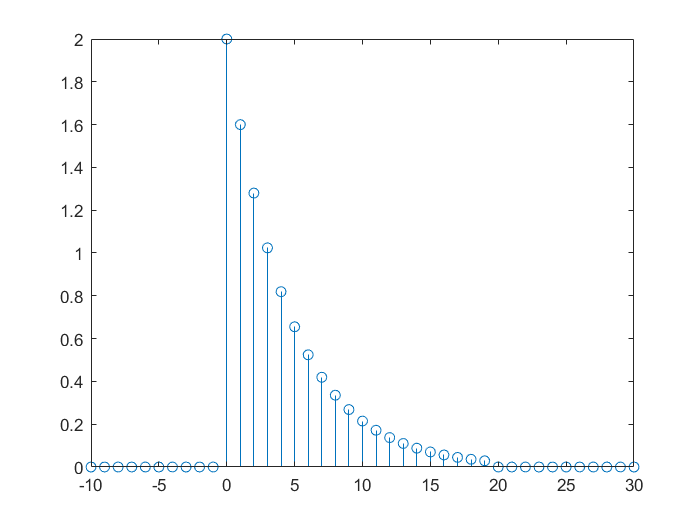

x1=2*0.8.^n1.*(escalon(n1,0)-escalon(n1,20));
figure;stem(n1,x1)

w1=linspace(-pi,pi,100)

w1 =    -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -0.0317


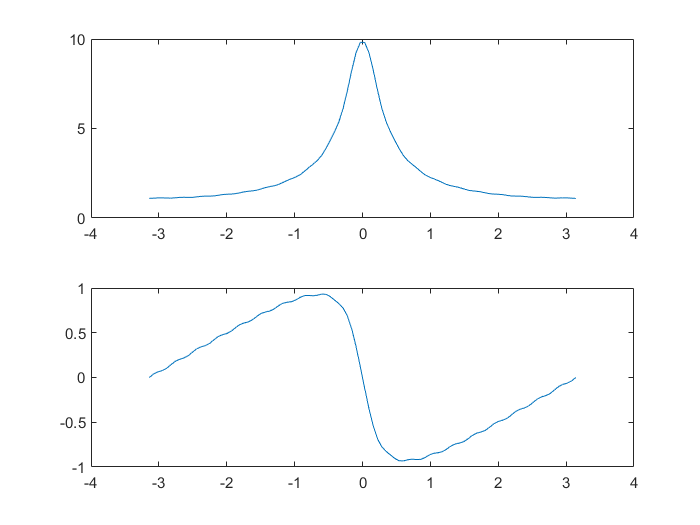

X1=DTFT(x1,n1,w1);
figure;subplot(211);
plot(w1,abs(X1))
subplot(212);
plot(w1,angle(X1))

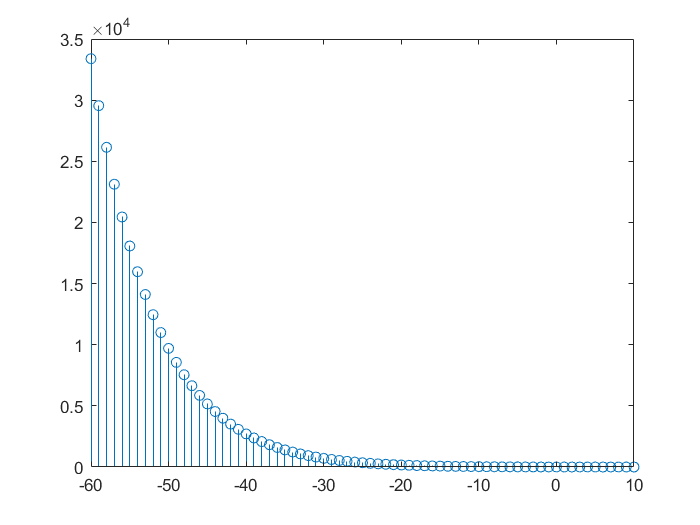

n2=-60:10;
x2=n2.*0.9.^n2.*(escalon(n2,0)-escalon(50,0)); %ojo al segundo escalon
figure;stem(n2,x2);

w2=linspace(-pi,pi,100)

w2 =    -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -0.0317


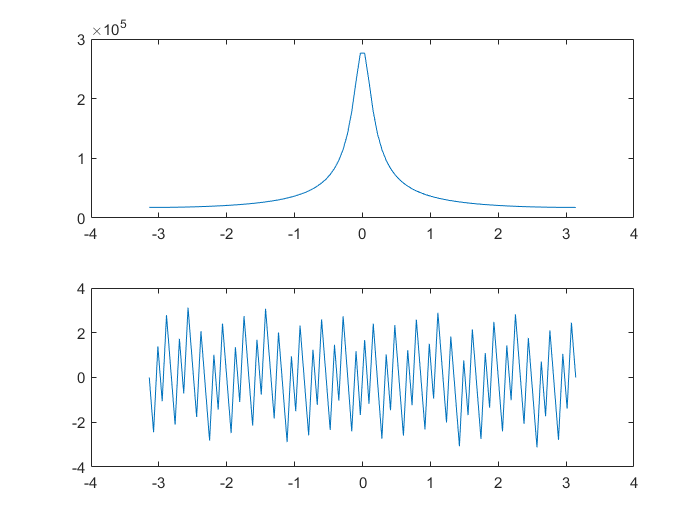

X2=DTFT(x2,n2,w2);
figure;subplot(211);
plot(w2,abs(X2))
subplot(212);
plot(w2,angle(X2)) %Es una funcion que va a dar mal siempre por ser descompensada pues no se

%llega a cortar en un sitio

x3=[4,3,2,1,2,3,4]

x3 =      4     3     2     1     2     3     4


n3=0:length(x3)-1 %De esta manera indico que el 0 esta en el 4

n3 =      0     1     2     3     4     5     6


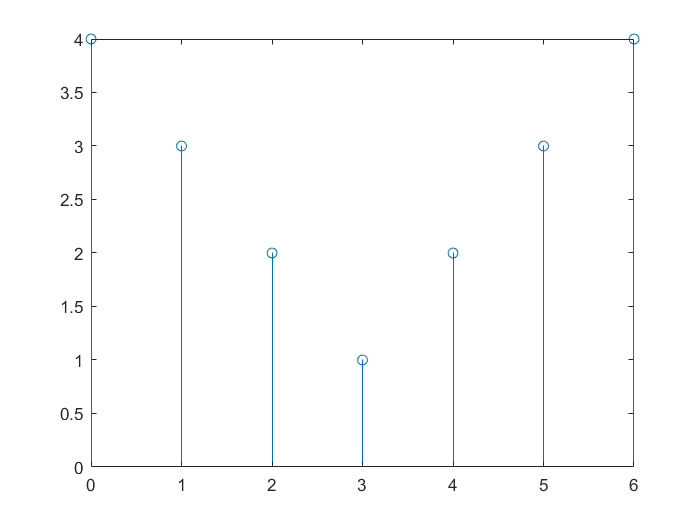

%La longitud de x debe ser igual a la de n, le resto 1 porque n empieza 0
figure;stem(n3,x3)

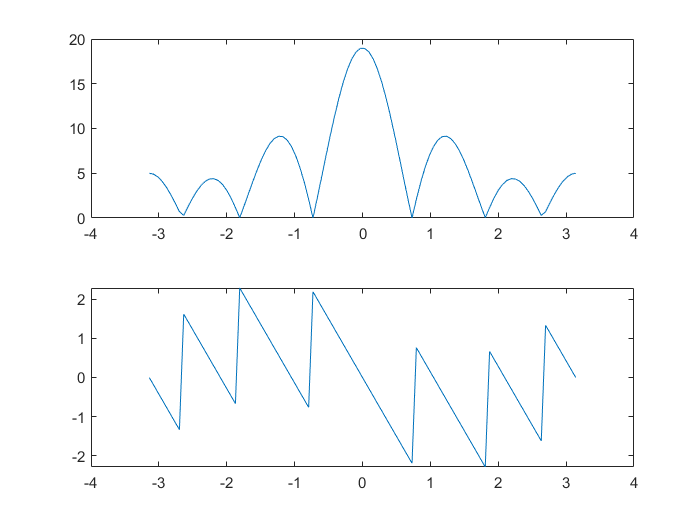

w3=linspace(-pi,pi,100);
X3=DTFT(x3,n3,w3);
subplot(211);
plot(w3,abs(X3))
subplot(212);
plot(w3,angle(X3))

%vemos que la grafica saldria mas bonita si el 0 estuviese en el centro ya
%que convertiria la funcion en simetrica

x4=[4,3,2,1,1,2,3,4]

x4 =      4     3     2     1     1     2     3     4


n4=0:length(x4)-1

n4 =      0     1     2     3     4     5     6     7


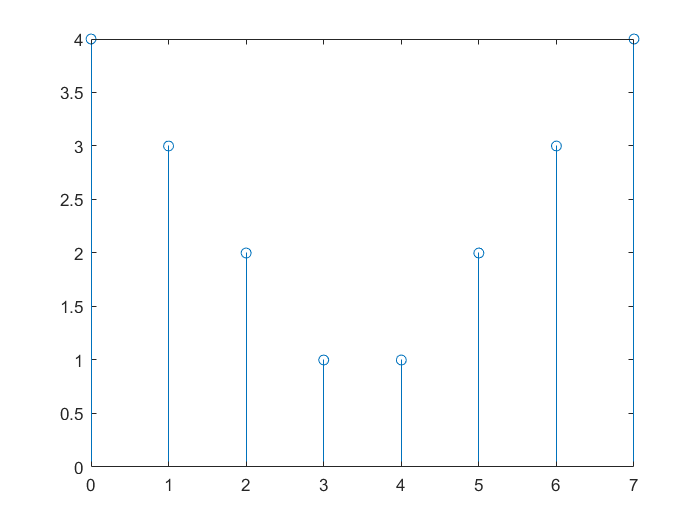

figure;stem(n4,x4)

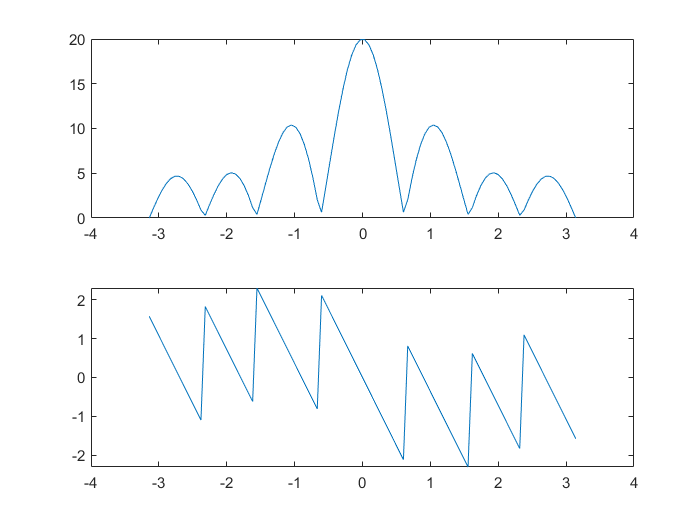

w4=linspace(-pi,pi,100);
X4=DTFT(x4,n4,w4);
subplot(211);
plot(w4,abs(X4))
subplot(212);
plot(w4,angle(X4)) %

x5=[4,3,2,1,0,-1,-2,-3,-4]

x5 =      4     3     2     1     0    -1    -2    -3    -4


n5=0:length(x5)-1

n5 =      0     1     2     3     4     5     6     7     8


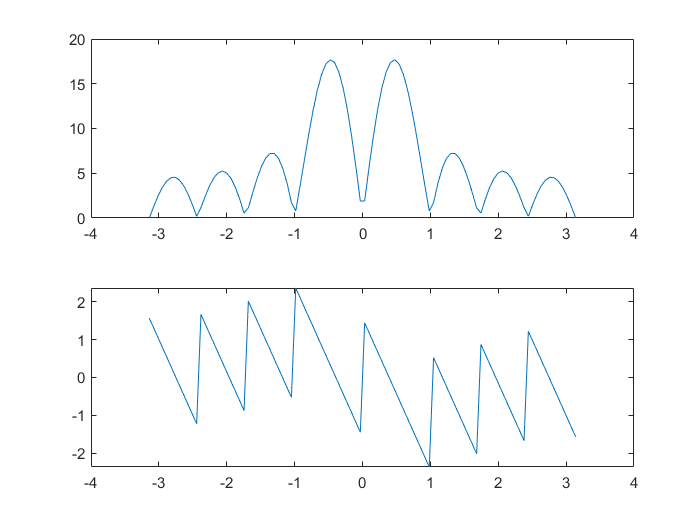

stem(n5,x5)
w5=linspace(-pi,pi,100);
X5=DTFT(x5,n5,w5);
subplot(211);
plot(w5,abs(X5))
subplot(212);
plot(w5,angle(X5))

n6=0:10 %en funcion escalon no hay valores negativos

n6 =      0     1     2     3     4     5     6     7     8     9    10


x6=3*(0.9)^3.*escalon(n6,0)

x6 =     2.1870    2.1870    2.1870    2.1870    2.1870    2.1870    2.1870    2.1870    2.1870    2.1870    2.1870


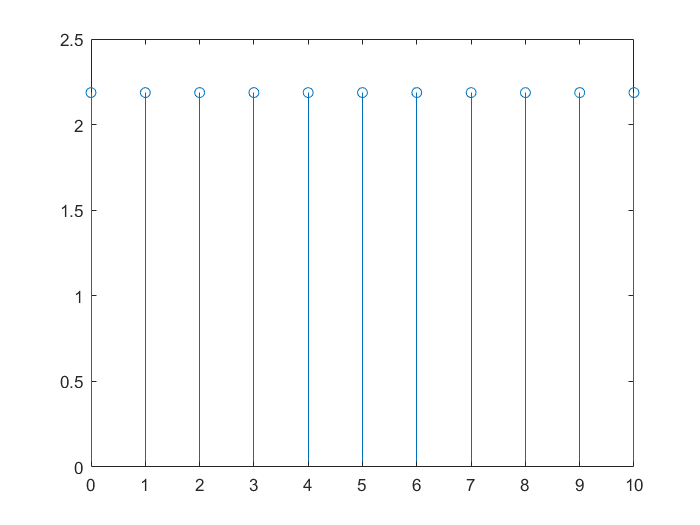

figure;stem(n6,x6)

w6=linspace(-pi,pi,100)

w6 =    -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -0.0317


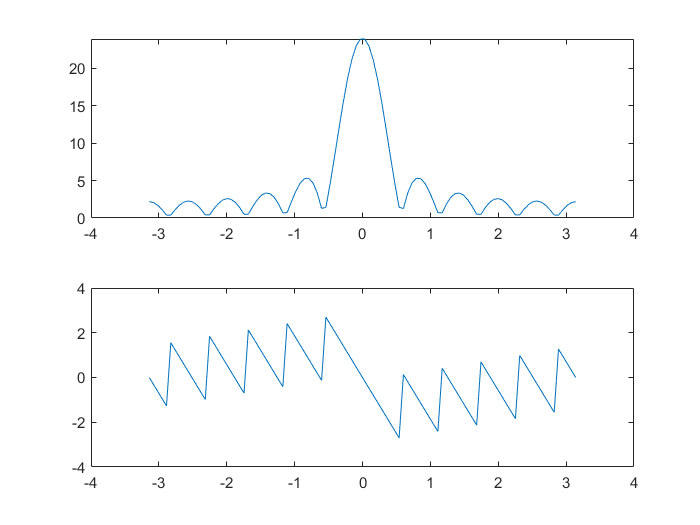

X6=DTFT(x6,n6,w6);
figure;subplot(211);
plot(w6,abs(X6))
subplot(212);
plot(w6,angle(X6))

n7=-5:20 %como minimo necesito del 0 al 2

n7 =     -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


x7=2*(0.8).^(n7+2).*escalon(n7,2)

x7 =          0         0         0         0         0         0         0    0.8192    0.6554    0.5243    0.4194    0.3355    0.2684    0.2147    0.1718    0.1374    0.1100    0.0880    0.0704    0.0563    0.0450    0.0360    0.0288    0.0231    0.0184    0.0148


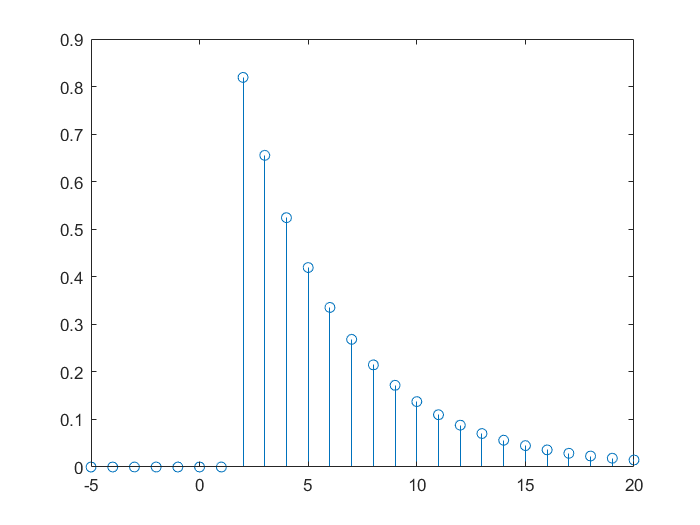

figure;stem(n7,x7)

w7=linspace(-pi,pi,100)

w7 =    -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -0.0317


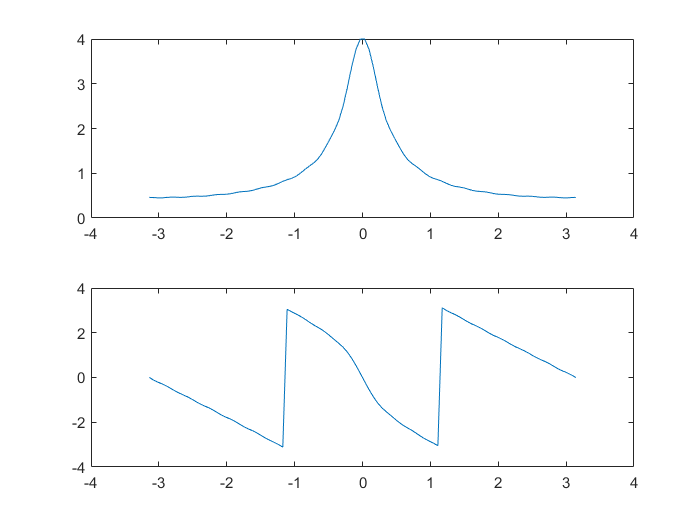

X7=DTFT(x7,n7,w7);
figure;subplot(211);
plot(w7,abs(X7))
subplot(212);
plot(w7,angle(X7))

n8=0:50

n8 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x8=n8.*(0.5).^n8.*escalon(n8,0)

x8 =          0    0.5000    0.5000    0.3750    0.2500    0.1562    0.0938    0.0547    0.0312    0.0176    0.0098    0.0054    0.0029    0.0016    0.0009    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


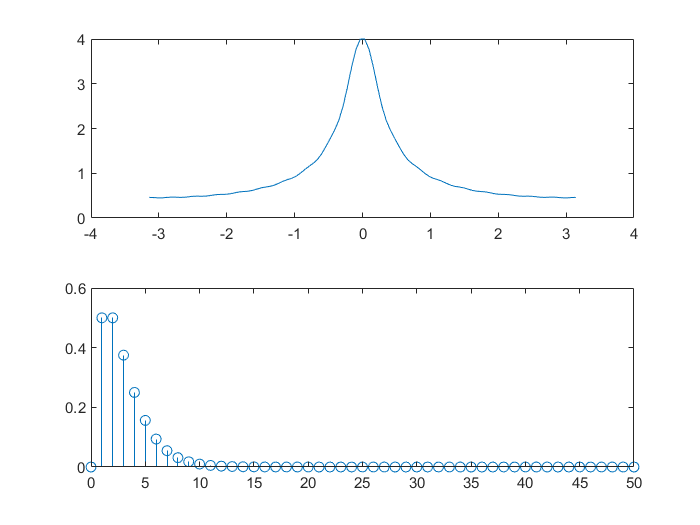

stem(n8,x8)

w8=linspace(-pi,pi,100)

w8 =    -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -0.0317


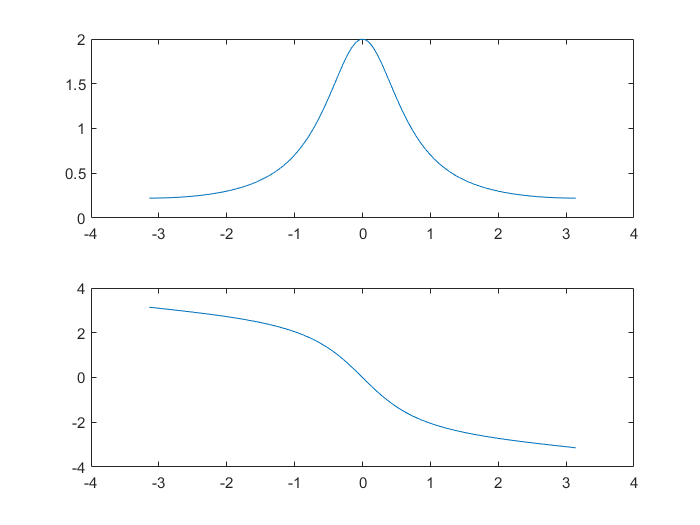

X8=DTFT(x8,n8,w8);
figure;subplot(211);
plot(w8,abs(X8))
subplot(212);
plot(w8,angle(X8))

n9=0:20

n9 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


x9=(n9+2).*(-0.7).^(n9-1).*escalon(n9,2)

x9 =          0         0   -2.8000    2.4500   -2.0580    1.6807   -1.3446    1.0588   -0.8235    0.6341   -0.4842    0.3672   -0.2768    0.2076   -0.1550    0.1153   -0.0855    0.0631   -0.0465    0.0342   -0.0251


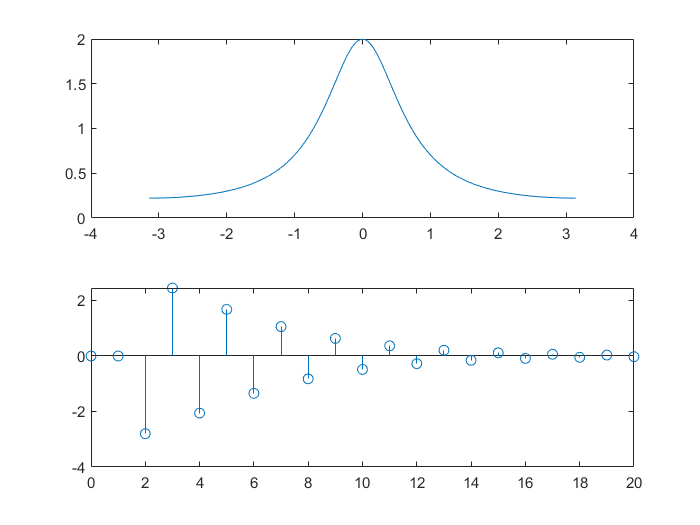

stem(n9,x9)

w9=linspace(-pi,pi,100)

w9 =    -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -0.0317


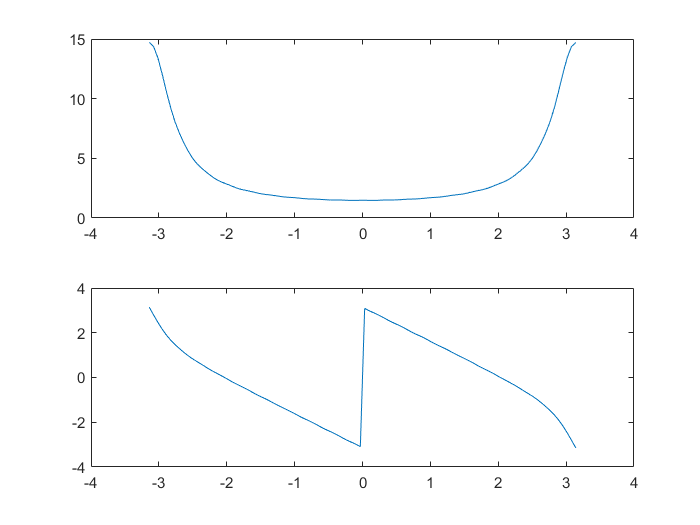

X9=DTFT(x9,n9,w9);
figure;subplot(211);
plot(w9,abs(X9))
subplot(212);
plot(w9,angle(X9))

n10=0:50

n10 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x10=5.*(-0.9).^n10.*cos(0.1*pi.*n10).*escalon(n10,0)

x10 =     5.0000   -4.2798    3.2765   -2.1425    1.0137   -0.0000   -0.8211    1.4057   -1.7413    1.8423   -1.7434    1.4923   -1.1425    0.7470   -0.3535    0.0000    0.2863   -0.4901    0.6071   -0.6424    0.6079   -0.5203    0.3983   -0.2605    0.1232   -0.0000   -0.0998    0.1709   -0.2117    0.2240   -0.2120    0.1814   -0.1389    0.0908   -0.0430    0.0000    0.0348   -0.0596    0.0738   -0.0781    0.0739   -0.0633    0.0484   -0.0317    0.0150   -0.0000   -0.0121    0.0208   -0.0257    0.0272


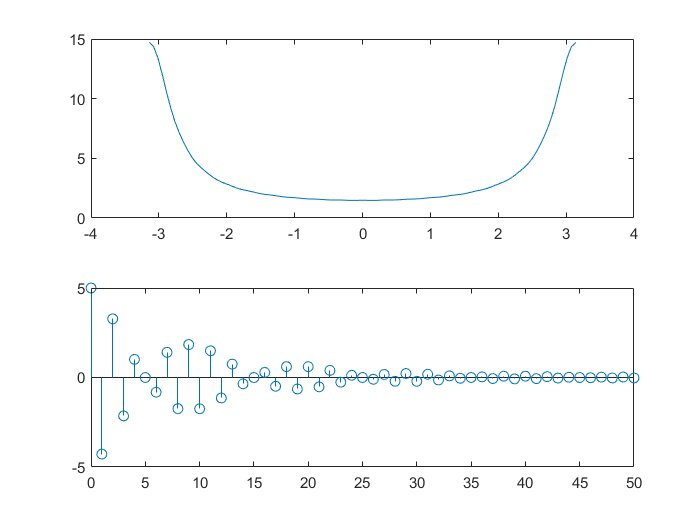

stem(n10,x10)

w10=linspace(-pi,pi,100)

w10 =    -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -0.0317


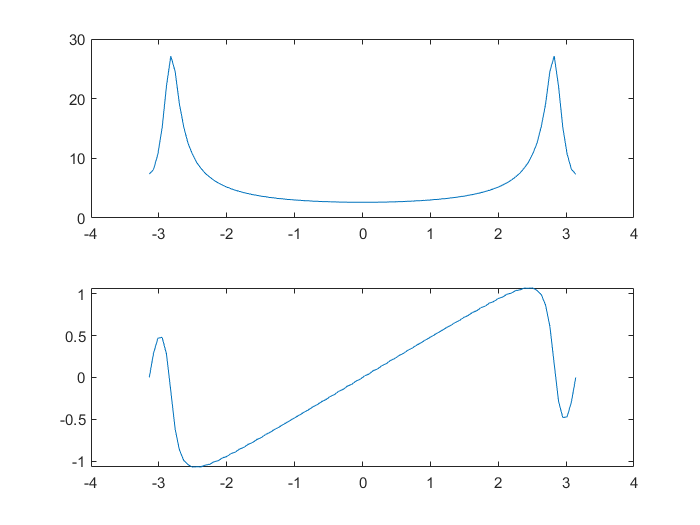

X10=DTFT(x10,n10,w10);
figure;subplot(211);
plot(w10,abs(X10))
subplot(212);
plot(w10,angle(X10))

## FILTROS

FILTRO RECTANGULAR: . Calcula la DTFT para N =5y N = 25. Dibuja la DTFT en el intervalo [-pi, pi]

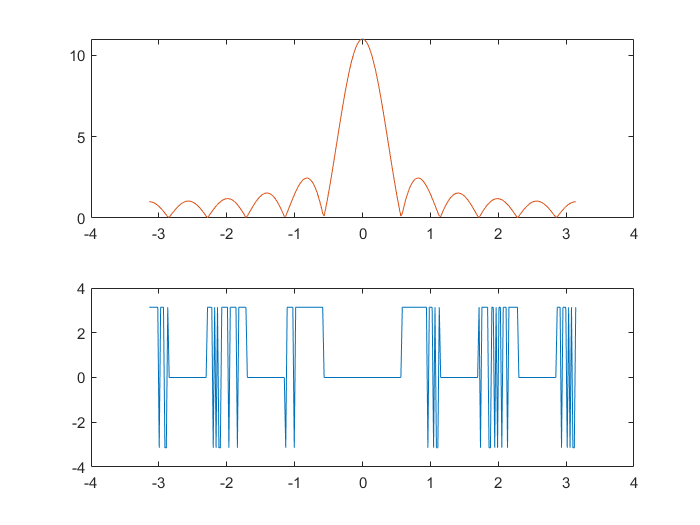

w=linspace(-pi,pi,301);
%
N=5;
n=linspace(-N,N,2*N+1); %la funcion va de -5 a 5 y el total de valores son 2*5+1=11
rn=ones(size(n)); %directamente asigna el valor 1 a los que tiene que asignarselo
Rn=DTFT(rn,n,w);
Rna=sin(w*(N+1/2))./sin(w/2);
figure;subplot(211);plot(w,abs(Rn),w,abs(Rna));
subplot(212);plot(w,angle(Rn));

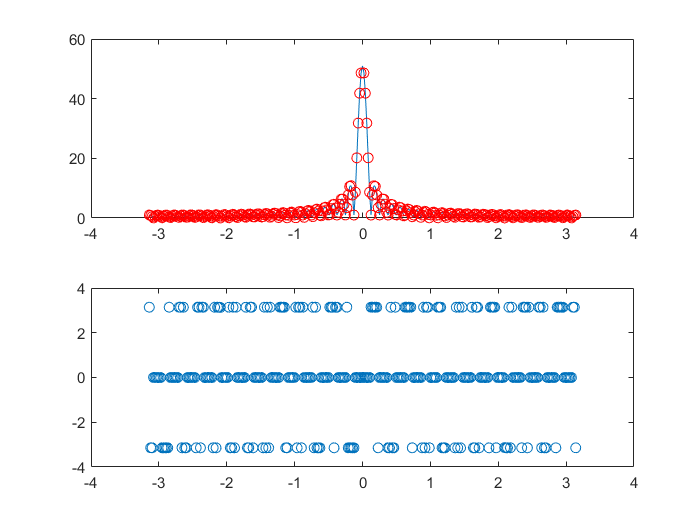

N=25;
n=linspace(-N,N,2*N+1);
rn=ones(size(n));
Rn=DTFT(rn,n,w);
Rna=sin(w*(N+1/2))./sin(w/2);
figure;subplot(211);plot(w,abs(Rn),w,abs(Rna),'ro');
subplot(212);plot(w,angle(Rn),'o');

FILTRO TRIANGULAR

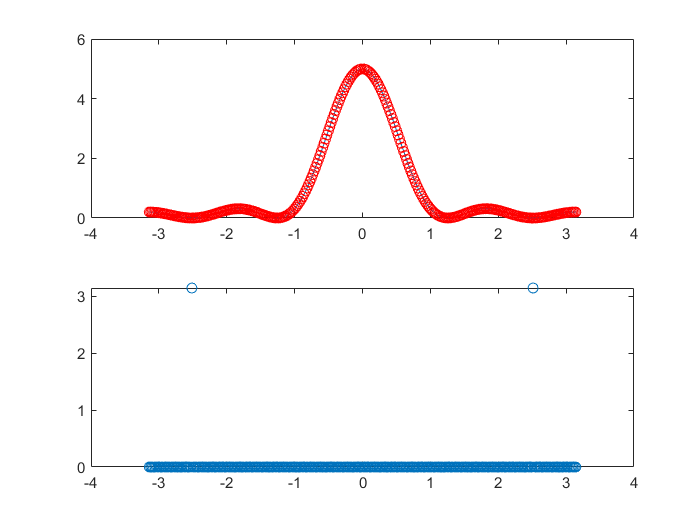

N=5;
n=linspace(-N,N,2*N+1);
tn=1-abs(n)/N;
Tn=DTFT(tn,n,w);
Tna=(sin(w*N/2)).^2./(N*(sin(w/2)).^2);
figure;subplot(211);plot(w,abs(Tn),w,abs(Tna),'ro');
subplot(212);plot(w,angle(Tn),'o');

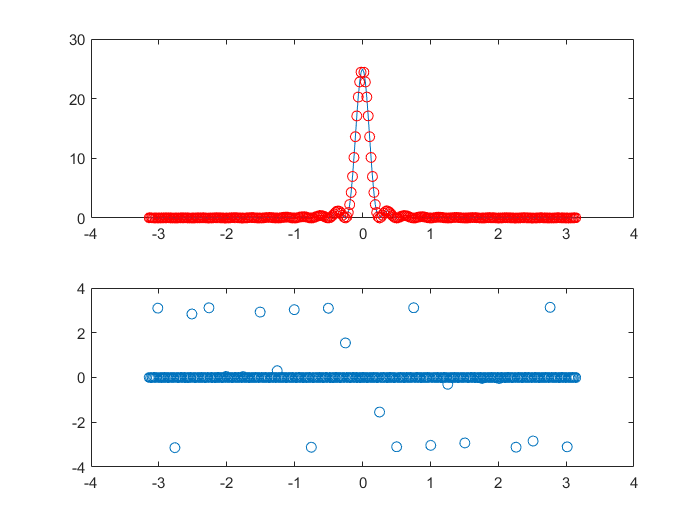

N=25;
n=linspace(-N,N,2*N+1);
tn=1-abs(n)/N;
Tn=DTFT(tn,n,w);
Tna=(sin(w*N/2)).^2./(N*(sin(w/2)).^2);
figure;subplot(211);plot(w,abs(Tn),w,abs(Tna),'ro');
subplot(212);plot(w,angle(Tn),'o');

FILTRO COSENO ALZADO

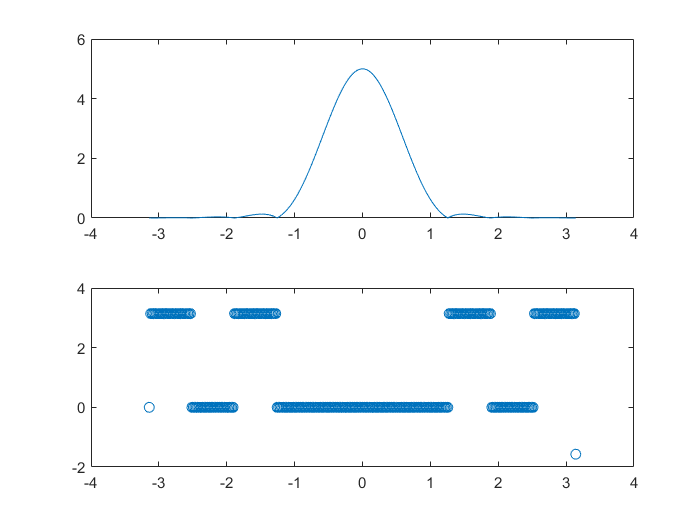

N=5;
n=linspace(-N,N,2*N+1);
cn=0.5+0.5*cos(pi*n/N);
Cn=DTFT(cn,n,w);
figure;subplot(211);plot(w,abs(Cn));
subplot(212);plot(w,angle(Cn),'o');

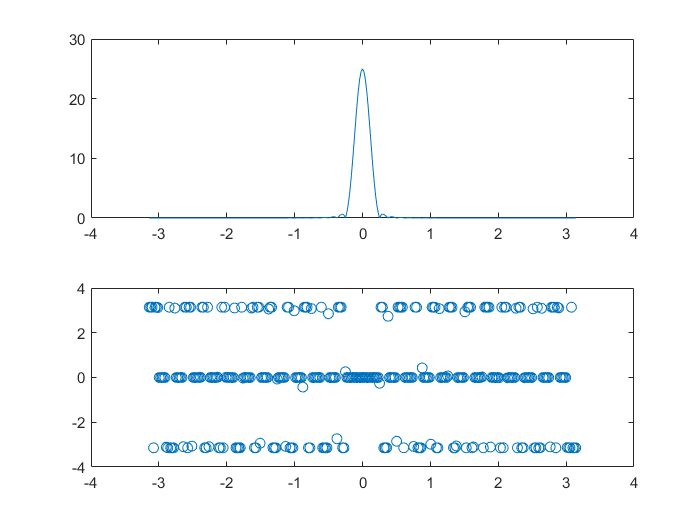

N=25;
n=linspace(-N,N,2*N+1);
cn=0.5+0.5*cos(pi*n/N);
Cn=DTFT(cn,n,w);
figure;subplot(211);plot(w,abs(Cn));
subplot(212);plot(w,angle(Cn),'o');